ant =   dipole with properties:

        Length: 2
         Width: 0.1000
    FeedOffset: 0
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


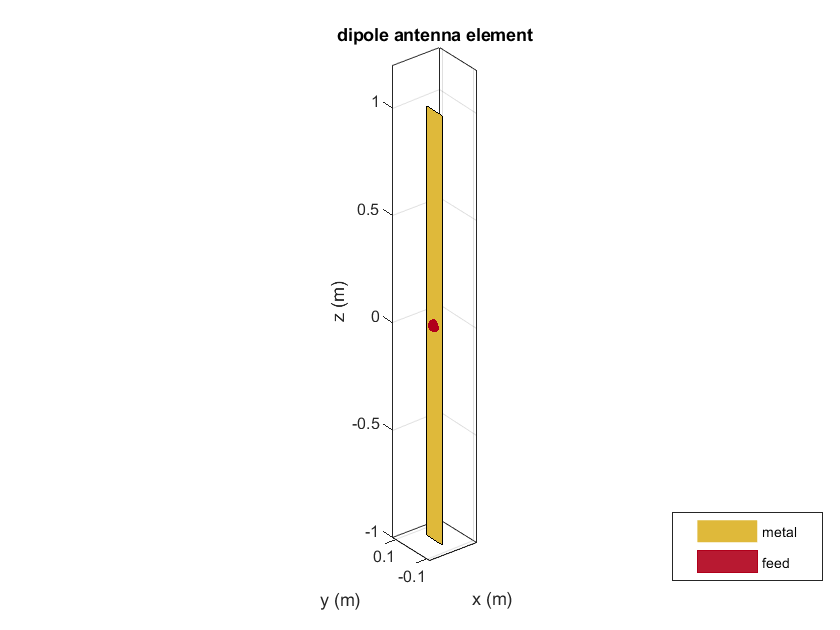

Out of memory.

Error in em.EmStructures/solver

Error in em.EmStructures/momsolver

Error in em.EmStructures/analyze

Error in em.FieldAnalysisWithFeed/pattern (line 179)
analyze(obj,frequency,ElemNumber,parseobj.Results.Termination);

Related documentation

ant = waveguideCircular_antennaDesigner
ant.Tilt = -90;
ant.TiltAxis = 'y';
show(ant)
pattern(ant,2.442e9)
%s=sparameters(ant,linspace(2.197e9,2.686e9,45));
%rfplot(s);
%figure;
%impedance(ant,linspace(2.197e9,2.686e9,45));
%patternAzimuth(ant,2.442e9)
tx = txsite('Name', 'Cantenna A', 'Antenna', ant, 'Latitude', 51.264793, 'Longitude', -1.452258,'TransmitterPower',1)
show(tx)
rx = rxsite('Name', 'Cantenna B', 'Antenna', ant, 'Latitude', 51.22881754, 'Longitude', -1.46736136)
show(rx)
%tx.AntennaAngle = angle(tx, rx(1));
coverage(tx,'rain','SignalStrengths',-80)
link(rx,tx,'rain')
coverage(tx,rx)